# Simple iterativeDisplay example 

This program illustrate the basic usage of the toolbox.

First write your code. As an example, the following program displays a sine wave with varying frequency.

Then, modify the code by including "`id.`" in front of every Matlab's graphic command.

You also need to add the following code at the begining of the loop.

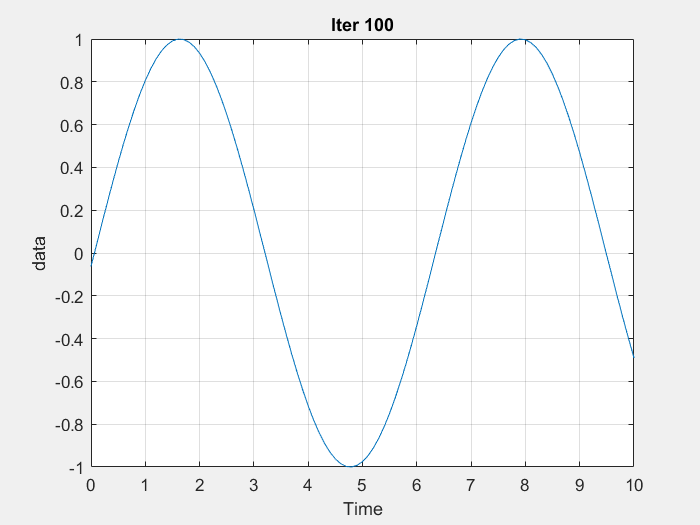

clearvars
close all
clc

id=iterativeDisplay();
n=100; % Number of iterations
t=0:0.1:10;

% Create figure
hfig=id.figure;
% Undock figure from livescript as it is to slow
set(hfig,'visible','on'); 

for i=1:n
    % Add this piece of code at the begining of your main loop
    if i<n
        % Start a new iteration
        id.newIteration;
    else
        % Last iteration needs to be indicated
        id.finalIteration;
    end

    id.plot(t,sin(t+2*pi*(i-1)/n)); % Plot some data
    id.grid('on');
    id.xlabel('Time');
    id.ylabel('data');
    id.title("Iter "+i);
    drawnow; % Force display update
end